# **Project#1: EngineFaultDB - Feature Extraction**

**Class: Industrial AI & Automation**

**Author: GYEONHEAL AN(21900416), GARMA JIN(21900xxx)**

**Contents**

**1. Data Prepartion**

**2. Data Preprocessing**

-     결측치 확인

-     이상치 확인

-     Correlation Check

-     Min-Max Scaling

**3. Feature Extraction**

- Time-Domain Feature Extraction

- Freq-Domain Feature Extraction

addpath("../../../Library");

## 1. Data Prepartion

clc; clear; close all;

Data_location = "../Datasets/EngineFaultDB_Final.xlsx";
Engine_datasets = readtable(Data_location, 'VariableNamingRule', 'preserve');

% Sampling Freq
fs = 10;
Engine_datasets.Properties

ans =   TableProperties - 속성 있음:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'Fault'  'MAP'  'TPS'  'Force'  'Power'  'RPM'  'Consumption L/H'  'Consumption L/100KM'  'Speed'  'CO'  'HC'  'CO2'  'O2'  'Lambda'  'AFR'}
           VariableTypes: ["double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"    "double"]
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: 사용자 지정 속성을 설정하지 않았습니다.
 addprop 및 rmprop을(를) 사용하여 CustomProperties를 수정하십시오.


**Time - Domain Analysis**

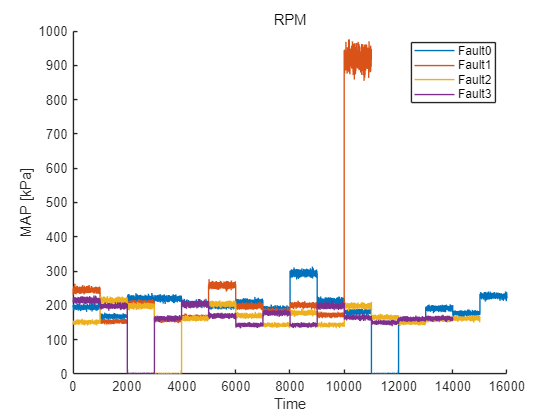

% Data Length Configuration
L0 = height(find(Engine_datasets.Fault == 0)); % Fault 0 : 16,000
L1 = height(find(Engine_datasets.Fault == 1)); % Fault 1 : 10,988
L2 = height(find(Engine_datasets.Fault == 2)); % Fault 2 : 15,000
L3 = height(find(Engine_datasets.Fault == 3)); % Fault 3 : 14,001

figure;
hold on;
plot((1:L0), Engine_datasets(Engine_datasets.Fault == 0, :).HC);
plot((1:L1), Engine_datasets(Engine_datasets.Fault == 1, :).HC);
plot((1:L2), Engine_datasets(Engine_datasets.Fault == 2, :).HC);
plot((1:L3), Engine_datasets(Engine_datasets.Fault == 3, :).HC);
legend('Fault0', 'Fault1', 'Fault2', 'Fault3')
xlabel("Time");
ylabel("MAP [kPa]");
title("RPM");

## 2. Data Preprocessing

### 2.1. 결측치 제거

결측치가 많은 Variables 제거 / MAP, Force, Power, CO, HC

data_fault0 = Engine_datasets(Engine_datasets.Fault == 0, :);
data_fault1 = Engine_datasets(Engine_datasets.Fault == 1, :);
data_fault2 = Engine_datasets(Engine_datasets.Fault == 2, :);
data_fault3 = Engine_datasets(Engine_datasets.Fault == 3, :);

% lowqual_vars = [4; 5; 10; 11];
% 
% data_fault0(:, lowqual_vars) = [];
% data_fault1(:, lowqual_vars) = [];
% data_fault2(:, lowqual_vars) = [];
% data_fault3(:, lowqual_vars) = [];

### 2.2. 노이즈, 이상치 확인 및 제거

Fault1의 데이터셋이 총 10998개까지 있으므로, 1000 개의 Datasets씩, 10000 개의 Datasets들을 처리함.

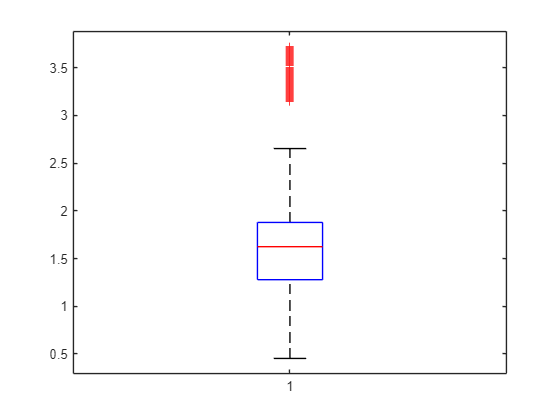

figure;
boxplot(data_fault3.MAP)

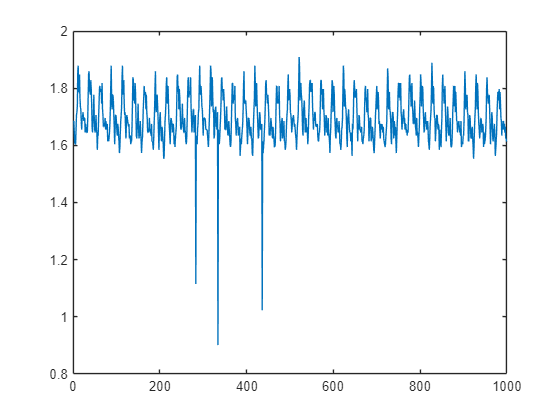

plot(data_fault3.MAP(1:1000,:))

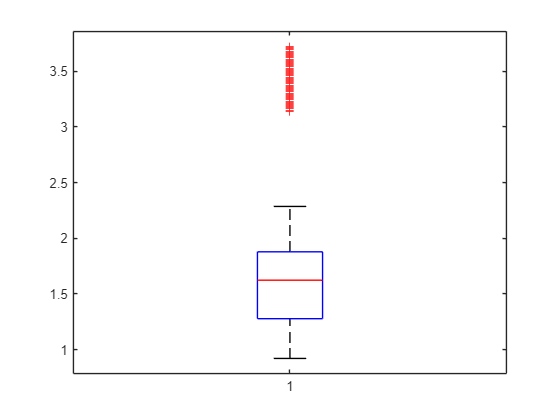

data_faults = {data_fault0, data_fault1, data_fault2, data_fault3};

for i = 1:4
    for t = 1000:1000:10000
        outliers = isoutlier(data_faults{i}(t-999:t, :));
        data_faults{i}(t-999:t, :) = filloutliers(data_faults{i}(t-999:t, :), 'linear');
    end
end

%% Update
data_fault0 = data_faults{1};
data_fault1 = data_faults{2};
data_fault2 = data_faults{3};
data_fault3 = data_faults{4};
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

boxplot(data_fault3.MAP)

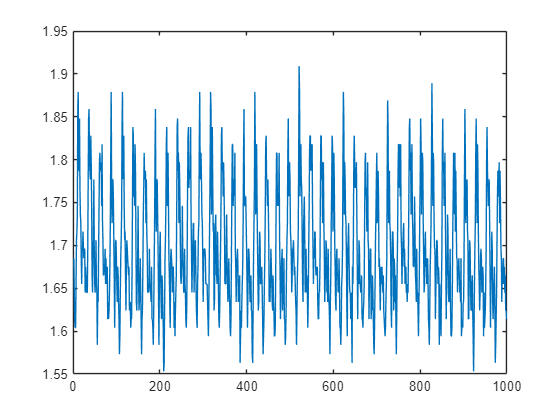

plot(data_fault3.MAP(1:1000,:))

### 2.3. Correlation Check

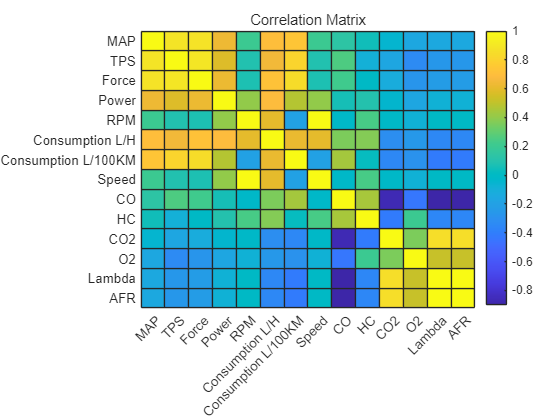

figure;
variable_names = datasets.Properties.VariableNames(2:end);
corr_matrix = corrcoef(table2array(datasets(:, 2:end)));
heatmap(corr_matrix, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Correlation Matrix', 'Colormap', parula);

disp(corr_matrix);

    1.0000    0.8844    0.8803    0.6295    0.2013    0.6979    0.7396    0.2011    0.1343    0.0443   -0.0496   -0.1577   -0.1449   -0.1449
    0.8844    1.0000    0.8916    0.5826    0.0928    0.6480    0.8070    0.0925    0.2538   -0.0987   -0.1641   -0.3309   -0.2619   -0.2619
    0.8803    0.8916    1.0000    0.6214    0.0724    0.7198    0.8484    0.0718    0.2167   -0.0027   -0.1261   -0.2742   -0.2318   -0.2318
    0.6295    0.5826    0.6214    1.0000    0.4035    0.6952    0.4730    0.4058    0.0604    0.1010   -0.0411   -0.1617   -0.0788   -0.0788
    0.2013    0.0928    0.0724    0.4035    1.0000    0.6034   -0.1980    0.9969   -0.0205    0.2362   -0.0156   -0.0801   -0.0038   -0.0037
    0.6979    0.6480    0.7198    0.6952    0.6034    1.0000    0.6141    0.6032    0.3584    0.3748   -0.3133   -0.2521   -0.3479   -0.3478
    0.7396    0.8070    0.8484    0.4730   -0.1980    0.6141    1.0000   -0.1973    0.4413    0.0270   -0.3500   -0.2904   -0.4139   -0.4139
    0.2011   

**연관성 높은 Variables 제거**

corr_threshold = 0.8;
high_corr = abs(corr_matrix) > corr_threshold

high_corr = 14×14 logical 배열
   1   1   1   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   0   0   0   1   0   0   0   0   0   0   0
   1   1   1   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   1   0   0   0   0   0   0   0   0
   0   1   1   0   0   0   1   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   1   0   1   0   1   1
   0   0   0   0   0   0   0   0   0   1   0   0   0   0


high_corr = high_corr - eye(size(high_corr));
[rows, cols] = find(high_corr);

correlated_vars = unique(max(rows, cols));
variable_names = datasets.Properties.VariableNames(2:end);
vars_to_remove = variable_names(correlated_vars);

disp(['Removed variables: ', strjoin(vars_to_remove, ', ')]);

Removed variables: TPS, Force, Consumption L/100KM, Speed, CO2, Lambda, AFR


% 높은 연관성을 가진 데이터 제거
% datasets(:, correlated_vars+1)=[];

### 2.4. Min-Max Scaling

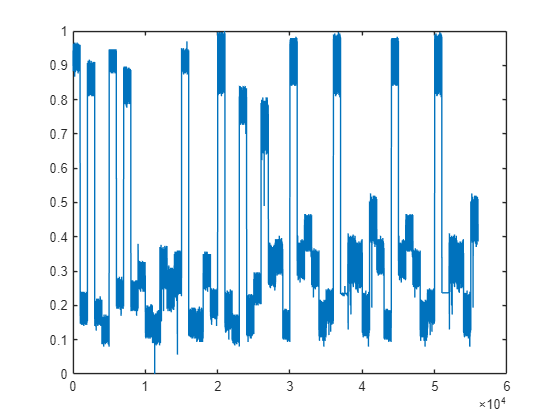

variables = datasets.Properties.VariableNames(2:end);

for i = 1:length(variables)

    datasets.(variables{i}) = normalize(datasets.(variables{i}), 'range');
end
figure;
plot(datasets.MAP);

### 2.5. Data Cutoff

data_fault0 = datasets(1:10000,:);
data_fault1 = datasets(L0+1:L0+10000, :);
data_fault2 = datasets(L0+L1+1:L0+L1+10000, :);
data_fault3 = datasets(L0+L1+L2+1:L0+L1+L2+10000, :);
datasets = [data_fault0; data_fault1; data_fault2; data_fault3];

filename = 'EngineFaultDB_Preprocessed.xlsx';
writetable(datasets, filename);

### 2.x. 각 Fault별 Correlation Check

data_fault0 : 정상

data_fault1 : Rich Mixture 

- 높은 Fuel Pressure

- Incorrect Sensor Performance

- Defective Injector

- Faulty Pressure Regulator

- Clogged Air Filter

- Clogged Fuel return line

--> MAP(Manifold 내부의 압력), TPS,  

data_fault2 : Lean Mixture

- Incorrect Sensor Performance

- Low fuel Pressure

- Defective Injector

- Faulty Pressure Regulator

data_fault3 : Low Voltage

- Worn Spark plugs

- Faulty Ignition Cables

- Defective Coils

- Faulty sensor wiring

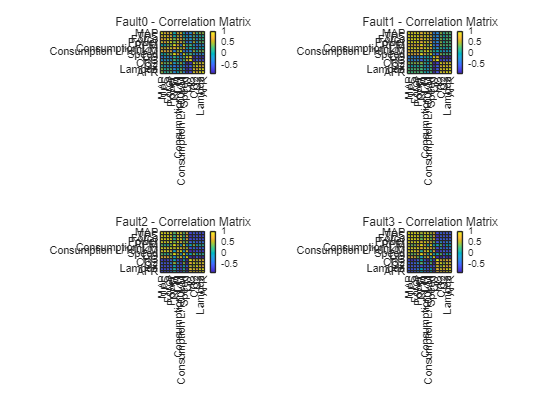

figure;
subplot(2,2,1);
variable_names = data_fault0.Properties.VariableNames(2:end);
corr_matrix_0 = corrcoef(table2array(data_fault0(:, 2:end)));
heatmap(corr_matrix_0, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault0 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,2);
variable_names = data_fault1.Properties.VariableNames(2:end);
corr_matrix_1 = corrcoef(table2array(data_fault1(:, 2:end)));
heatmap(corr_matrix_1, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault1 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,3);
variable_names = data_fault2.Properties.VariableNames(2:end);
corr_matrix_2 = corrcoef(table2array(data_fault2(:, 2:end)));
heatmap(corr_matrix_2, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault2 - Correlation Matrix', 'Colormap', parula);

subplot(2,2,4);
variable_names = data_fault3.Properties.VariableNames(2:end);
corr_matrix_3 = corrcoef(table2array(data_fault3(:, 2:end)));
heatmap(corr_matrix_3, 'XData', variable_names, 'YData', variable_names, ...
    'Title', 'Fault3 - Correlation Matrix', 'Colormap', parula);

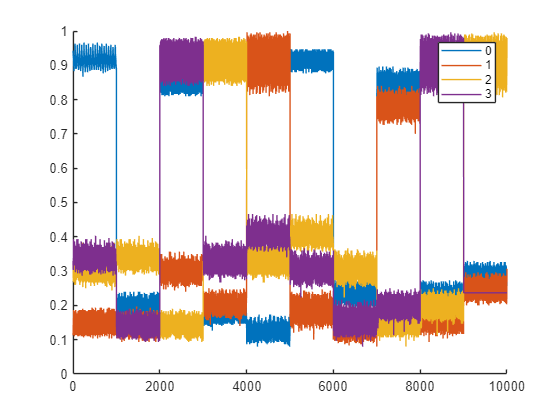

figure;
hold on;
plot(data_fault0.MAP);
plot(data_fault1.MAP);
plot(data_fault2.MAP);
plot(data_fault3.MAP);
hold off
legend('0', '1', '2', '3');

data_fault0

data_fault0 = 10000×15 table
    Fault      MAP        TPS        Force       Power       RPM       Consumption L/H    Consumption L/100KM      Speed         CO          HC         CO2        O2       Lambda       AFR  
    _____    _______    _______    _________    _______    ________    _______________    ___________________    _________    _________    _______    _______    _______    _______    _______

      0      0.93979    0.39252    0.0031898    0.14233    0.027178       0.086933              0.44646           0.015804    0.0037083    0.19952    0.88701    0.93569    0.84819    0.84822
      0      0.94306    0.39533    0.0033335    0.14532    0.015064       0.075823              0.41611           0.017341    0.0055624    0.19971    0.90814    0.96463    0.93494     0.9369
      0      0.93652    0.39533    0.0032887    0.13854    0.031185        0.08064              0.46053          0.0076103    0.0041203    0.20391    0.90053    0.95606    0.90843     0.9087
      0      0.

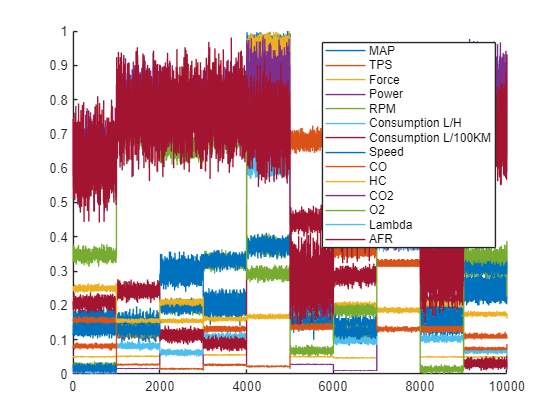


figure;
hold on;
for i = 2:width(data_fault1)
    plot(table2array(data_fault1(:,i)))
end
hold off;
legend(data_fault1.Properties.VariableNames(2:end))

% n개의 샘플을 가져오기 위한 변수 설정
n = 3000;  % 각 Fault 유형당 1000개의 샘플

% 입력 변수 (MAP, TPS, RPM, Power)
MAP = [data_fault0.MAP(1:n); data_fault1.MAP(1:n); data_fault2.MAP(1:n); data_fault3.MAP(1:n)];
TPS = [data_fault0.TPS(1:n); data_fault1.TPS(1:n); data_fault2.TPS(1:n); data_fault3.TPS(1:n)];
Force = [data_fault0.Force(1:n); data_fault1.Force(1:n); data_fault2.Force(1:n); data_fault3.Force(1:n)];
Power = [data_fault0.Power(1:n); data_fault1.Power(1:n); data_fault2.Power(1:n); data_fault3.Power(1:n)];
RPM = [data_fault0.RPM(1:n); data_fault1.RPM(1:n); data_fault2.RPM(1:n); data_fault3.RPM(1:n)];
ConsumptionLH = [data_fault0.("Consumption L/H")(1:n); data_fault1.("Consumption L/H")(1:n); data_fault2.("Consumption L/H")(1:n); data_fault3.("Consumption L/H")(1:n)];
ConsumptionL100 = [data_fault0.("Consumption L/100KM")(1:n); data_fault1.("Consumption L/100KM")(1:n); data_fault2.("Consumption L/100KM")(1:n); data_fault3.("Consumption L/100KM")(1:n)];
Speed = [data_fault0.Speed(1:n); data_fault1.Speed(1:n); data_fault2.Speed(1:n); data_fault3.Speed(1:n)];

% 출력 변수 (CO, HC, O2, Lambda)
CO = [data_fault0.CO(1:n); data_fault1.CO(1:n); data_fault2.CO(1:n); data_fault3.CO(1:n)];
HC = [data_fault0.HC(1:n); data_fault1.HC(1:n); data_fault2.HC(1:n); data_fault3.HC(1:n)];
O2 = [data_fault0.O2(1:n); data_fault1.O2(1:n); data_fault2.O2(1:n); data_fault3.O2(1:n)];
CO2 = [data_fault0.CO2(1:n); data_fault1.CO2(1:n); data_fault2.CO2(1:n); data_fault3.CO2(1:n)];
Lambda = [data_fault0.Lambda(1:n); data_fault1.Lambda(1:n); data_fault2.Lambda(1:n); data_fault3.Lambda(1:n)];
AFR = [data_fault0.AFR(1:n); data_fault1.AFR(1:n); data_fault2.AFR(1:n); data_fault3.AFR(1:n)];

% Fault 라벨 (0 = 정상, 1 = Rich Mixture, 2 = Lean Mixture, 3 = Low Voltage)
FaultLabels = [data_fault0.Fault(1:n); data_fault1.Fault(1:n); data_fault2.Fault(1:n); data_fault3.Fault(1:n)];

% 입력 데이터 (MAP, TPS, RPM, Power를 하나의 행렬로 결합)
X = [MAP, TPS, Force, Power, RPM, ConsumptionLH, ConsumptionL100, Speed];

% 출력 데이터 (CO, HC, O2, Lambda를 결합)
Y = [CO, HC, CO2, O2, Lambda, AFR];

% 1. 데이터 섞기
data_size = size(X, 1);  % 전체 데이터 크기
indices = randperm(data_size);  % 무작위로 인덱스 섞기

% 2. Train Set과 Test Set 나누기 (80:20)
train_size = round(0.8 * data_size);  % 전체 데이터의 80%
test_size = data_size - train_size;  % 나머지 20%

train_idx = indices(1:train_size);  % 학습 데이터 인덱스
test_idx = indices(train_size+1:end);  % 테스트 데이터 인덱스

% 3. 학습용 데이터셋
X_train = X(train_idx, :);
Y_train = Y(train_idx, :);
FaultLabels_train = FaultLabels(train_idx);

% 4. 테스트용 데이터셋
X_test = X(test_idx, :);
Y_test = Y(test_idx, :);
FaultLabels_test = FaultLabels(test_idx);

[coeff, score, ~] = pca(X_train);
X_train = score(:, 1:5);  % 상위 10개의 주성분만 사용

% tic
% % 5. MOGP 대신 각 출력 변수에 대해 가우시안 프로세스 회귀 모델 학습 (학습 데이터 사용)
% gprMdl_CO = fitrgp(X_train, Y_train(:, 1));  % CO 예측 모델
% gprMdl_HC = fitrgp(X_train, Y_train(:, 2));  % HC 예측 모델
% gprMdl_CO2 = fitrgp(X_train, Y_train(:, 3));  % O2 예측 모델
% gprMdl_O2 = fitrgp(X_train, Y_train(:, 4));  % O2 예측 모델
% gprMdl_Lambda = fitrgp(X_train, Y_train(:, 5));  % O2 예측 모델
% gprMdl_AFR = fitrgp(X_train, Y_train(:, 6));  % Lambda 예측 모델
% toc

tic
% 5. MOGP 대신 각 출력 변수에 대해 가우시안 프로세스 회귀 모델 학습 (학습 데이터 사용)
gprMdl_CO = fitrgp(X_train, Y_train(:, 1));  % CO 예측 모델
gprMdl_HC = fitrgp(X_train, Y_train(:, 2));  % HC 예측 모델
gprMdl_CO2 = fitrgp(X_train, Y_train(:, 3));  % O2 예측 모델
gprMdl_O2 = fitrgp(X_train, Y_train(:, 4));  % O2 예측 모델
gprMdl_Lambda = fitrgp(X_train, Y_train(:, 5));  % O2 예측 모델
gprMdl_AFR = fitrgp(X_train, Y_train(:, 6));  % Lambda 예측 모델
toc

경과 시간은 28.698236초입니다.


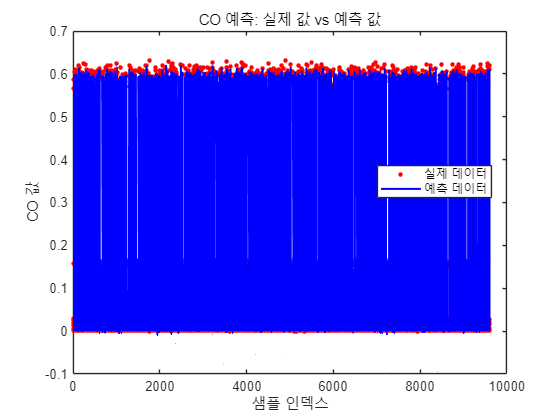

% 학습 데이터에 대해 CO 예측
ypred_CO_train = predict(gprMdl_CO, X_train);

% 실제 CO 값 (Y_train의 첫 번째 열)
actual_CO_train = Y_train(:, 1);

% 예측된 값과 실제 값을 비교하는 그래프 생성
figure();
plot(1:train_size, actual_CO_train, 'r.', 'MarkerSize', 10);  % 실제 CO 값
hold on;
plot(1:train_size, ypred_CO_train, 'b-', 'LineWidth', 1.5);  % 예측된 CO 값
xlabel('샘플 인덱스');
ylabel('CO 값');
legend({'실제 데이터', '예측 데이터'}, 'Location', 'Best');
title('CO 예측: 실제 값 vs 예측 값');
hold off;

% 6. 테스트 데이터에 대해 출력 변수 예측
Y_pred_test = zeros(test_size, 6);  % 예측된 출력 값을 저장할 행렬

for i = 1:test_size
    new_X = X_test(i, :);  % 테스트 데이터 샘플 가져오기
    
    % 예측 수행
    Y_pred_test(i, 1) = predict(gprMdl_CO, new_X);
    Y_pred_test(i, 2) = predict(gprMdl_HC, new_X);
    Y_pred_test(i, 3) = predict(gprMdl_CO2, new_X);
    Y_pred_test(i, 4) = predict(gprMdl_O2, new_X);
    Y_pred_test(i, 5) = predict(gprMdl_Lambda, new_X);
    Y_pred_test(i, 6) = predict(gprMdl_AFR, new_X);
end

다음 사용 중 오류가 발생함: classreg.learning.regr.CompactRegressionGP/predict (488번 라인)
X는 5개의 열을 가진 실수 숫자형 행렬이어야 합니다.


% 7. SVM 모델을 사용하여 Fault 분류 (학습 데이터 사용)
svmMdl = fitcecoc(Y_train, FaultLabels_train);  % 다중 클래스 SVM 모델 학습

% 8. 예측된 출력 변수들로 테스트 데이터의 Fault 유형 예측
predicted_faults = predict(svmMdl, Y_pred_test);

% 9. 혼돈 행렬 생성
confusionchart(FaultLabels_test, predicted_faults);
title('혼돈 행렬: 실제 vs 예측 Fault 유형');

confusion_matrix = confusionmat(FaultLabels_test, predicted_faults);

% 10. 평가 지표 계산 (Accuracy, Precision, Recall, F1 Score)
accuracy = sum(diag(confusion_matrix)) / sum(confusion_matrix(:))  % 정확도 계산

accuracy = 0.6587

precision = diag(confusion_matrix) ./ sum(confusion_matrix, 2)  % 각 클래스별 Precision

precision =     0.6593
    0.6596
    1.0000
    0.3201


recall = diag(confusion_matrix) ./ sum(confusion_matrix, 1)'    % 각 클래스별 Recall

recall =     0.6863
    1.0000
    0.4873
    1.0000


f1_score = 2 * (precision .* recall) ./ (precision + recall)  % 각 클래스별 F1-Score

f1_score =     0.6725
    0.7949
    0.6553
    0.4849


% n개의 샘플을 가져오기 위한 변수 설정
n = 1000;  % 원하는 샘플 수

% 입력 변수 (MAP, TPS, RPM, Power)
MAP = [data_fault0.MAP(1:n); data_fault1.MAP(1:n); data_fault2.MAP(1:n); data_fault3.MAP(1:n)];
TPS = [data_fault0.TPS(1:n); data_fault1.TPS(1:n); data_fault2.TPS(1:n); data_fault3.TPS(1:n)];
RPM = [data_fault0.RPM(1:n); data_fault1.RPM(1:n); data_fault2.RPM(1:n); data_fault3.RPM(1:n)];
Power = [data_fault0.Power(1:n); data_fault1.Power(1:n); data_fault2.Power(1:n); data_fault3.Power(1:n)];

% 출력 변수 (CO, HC, O2, Lambda)
CO = [data_fault0.CO(1:n); data_fault1.CO(1:n); data_fault2.CO(1:n); data_fault3.CO(1:n)];
HC = [data_fault0.HC(1:n); data_fault1.HC(1:n); data_fault2.HC(1:n); data_fault3.HC(1:n)];
O2 = [data_fault0.O2(1:n); data_fault1.O2(1:n); data_fault2.O2(1:n); data_fault3.O2(1:n)];
Lambda = [data_fault0.Lambda(1:n); data_fault1.Lambda(1:n); data_fault2.Lambda(1:n); data_fault3.Lambda(1:n)];

% Fault 라벨 (0 = 정상, 1 = Rich Mixture, 2 = Lean Mixture, 3 = Low Voltage)
FaultLabels = [data_fault0.Fault(1:n); data_fault1.Fault(1:n); data_fault2.Fault(1:n); data_fault3.Fault(1:n)];

% 입력 데이터 (MAP, TPS, RPM, Power를 하나의 행렬로 결합)
X = [MAP, TPS, RPM, Power];

% 출력 데이터 (CO, HC, O2, Lambda를 결합)
Y = [CO, HC, O2, Lambda];



% 2. MOGP 대신 각 출력 변수에 대해 가우시안 프로세스 회귀 모델 학습
gprMdl_CO = fitrgp(X, CO);  % CO 예측 모델
gprMdl_HC = fitrgp(X, HC);  % HC 예측 모델
gprMdl_O2 = fitrgp(X, O2);  % O2 예측 모델
gprMdl_Lambda = fitrgp(X, Lambda);  % Lambda 예측 모델


% 새로운 입력 데이터에 대해 출력 변수를 예측
test = 5802;
new_X = [data_fault1.MAP(test), data_fault1.TPS(test), data_fault1.RPM(test), data_fault1.Power(test)];  % 새로운 입력 데이터 (MAP, TPS, RPM, Power)

CO_pred = predict(gprMdl_CO, new_X);
HC_pred = predict(gprMdl_HC, new_X);
O2_pred = predict(gprMdl_O2, new_X);
Lambda_pred = predict(gprMdl_Lambda, new_X);

% 예측된 출력 변수들을 하나의 행렬로 결합
Y_pred = [CO_pred, HC_pred, O2_pred, Lambda_pred];

% 3. SVM 모델을 사용하여 Fault 분류
svmMdl = fitcecoc(Y, FaultLabels);  % 다중 클래스 SVM 모델 학습 (fitcecoc는 One-vs-All SVM 사용)

% 예측된 출력 변수들로 Fault 유형 예측
predicted_fault = predict(svmMdl, Y_pred);

% 결과 출력
disp('예측된 Fault 유형:');

예측된 Fault 유형:


disp(predicted_fault);

     3



MOGP

% % 입력 변수: 예를 들어 MAP, TPS, Force, RPM 등
% X = [datasets.MAP(1:1000), datasets.TPS(1:1000), datasets.Force(1:1000), datasets.RPM(1:1000), datasets.Speed(1:1000), datasets.Power(1:1000), datasets.("Consumption L/H")(1:1000), datasets.("Consumption L/100KM")(1:1000)];
% 
% % 출력 변수: 예를 들어 CO, HC, O2, Lambda, AFR 등
% Y = [datasets.CO(1:1000), datasets.HC(1:1000), datasets.CO2(1:1000), datasets.O2(1:1000), datasets.Lambda(1:1000), datasets.AFR(1:1000)];
% 
% % Fault 라벨: Fault0, Fault1, Fault2, Fault3
% FaultLabels = [0; 1; 2; 3];  % Fault 유형을 숫자로 정의

% % 각 출력 변수에 대한 가우시안 프로세스 회귀 모델을 학습
% gprMdl_CO = fitrgp(X, datasets.CO(1:1000));

% 
% gprMdl_HC = fitrgp(X, datasets.HC(1:1000));
% gprMdl_O2 = fitrgp(X, datasets.O2(1:1000));
% gprMdl_Lambda = fitrgp(X, datasets.Lambda(1:1000));
% gprMdl_AFR = fitrgp(X, datasets.AFR(1:1000));
% 

% new_X = [datasets.MAP(1001:2000), datasets.TPS(1001:2000), datasets.Force(1001:2000), datasets.RPM(1001:2000), datasets.Speed(1001:2000), datasets.Power(1001:2000), datasets.("Consumption L/H")(1001:2000), datasets.("Consumption L/100KM")(1001:2000)];
% CO_pred = predict(gprMdl_CO, new_X);
% HC_pred = predict(gprMdl_HC, new_X);
% O2_pred = predict(gprMdl_O2, new_X);
% Lambda_pred = predict(gprMdl_Lambda, new_X);
% AFR_pred = predict(gprMdl_AFR, new_X);
% Y_pred = [CO_pred, HC_pred, O2_pred, Lambda_pred, AFR_pred];

% 4. 로지스틱 회귀로 Fault 유형 분류
% logisticMdl = fitglm(Y_pred, FaultLabels, 'Distribution', 'binomial');
% Fault_pred = round(predict(logisticMdl, Y_pred));

% X = datasets(:, 2:end);  
% Y = datasets.Fault;   
% 
% % Test datasets : Train datasets = 2 : 8
% cv = cvpartition(Y, 'HoldOut', 0.2);  % 20%는 테스트셋으로 사용
% 
% % Training Datasets
% X_train = X(training(cv), :);
% Y_train = Y(training(cv), :);
% 
% % Test Datasets
% X_test = X(test(cv), :);
% Y_test = Y(test(cv), :);
% 
% % Seperate Train datasets and Validation datasets
% cv_train = cvpartition(Y_train, 'HoldOut', 0.125);  % 80% 중 1/8은 검증에 사용 (10%)
% 
% % Train Datasets
% X_train_final = X_train(training(cv_train), :);
% Y_train_final = Y_train(training(cv_train), :);
% 
% % Validation Datasets
% X_val = X_train(test(cv_train), :);
% Y_val = Y_train(test(cv_train), :);
% 
% svm_model = fitcecoc(X_train_final, Y_train_final);
% mlResubErr_svm = resubLoss(svm_model)
% 
% Y_pred = predict(svm_model, X_test);
% 
% confusion_matrix = confusionmat(Y_test, Y_pred);
% 
% confusionchart(confusion_matrix);
% 
% % 정확도 계산
% accuracy = sum(Y_pred == Y_test) / length(Y_test);
% 
% disp(['Accuracy: ', num2str(accuracy)]);